## Problem 3.

다음과 같은 1차 시스템을 고려하자. 


$$\dot{y} = ay + bu$$


여기서 시스템 파라미터의 참 값은 $a = -2,$ $b = 1$이나, 이 값은 정확히 알지 못한다고 가정하자. 시스템 파라미터의 추정 초기값으로 $\hat{a}_0 = 1,$ $\hat{b}_0 = 2$로 설정하자.

일차 시스템을 제어하기 위하여 Self-tuning 기법을 바탕으로 제어기를 설계하고자 한다. 이때 고려하는 제어기의 구조는 다음과 같다. 


$$u = k_1 r - k_2 y$$


clc; close all; clear all;

### a)

시스템 파라미터의 초기 값 ($\hat{a}_0 = 1,$ $\hat{b}_0 = 2$)을 고려하여 단위계단 입력 $r(t)$에 대한 추정오차가 $0$이 되고,  closed-loop pole $p = -2$ 가 되도록 하는 $k_1,$ $k_2$의 값을 구하여라

***sol)***

시스템 파라미터 초기 값을 고려한 $\dot{y} = \hat{a}_0 y + \hat{b}_0 u$의 Laplace transform은 $y(0) = 0$ 가정에서 $sY_m(s) = \hat{a}_0 Y_m(s) + \hat{b}_0 U(s)$이다. 제어기 $u = k_1r - k_2y$의 Laplace transform은 $U(s) = k_1 R(s) - k_2 Y_m(s)$이다. Closed-loop transfer function을 구해보면,


$$sY_m(s) = \hat{a}_0 Y_m(s) + \hat{b}_0 U(s) = \hat{a}_0 Y_m(s) + \hat{b}_0 (k_1 R(s) - k_2 Y_m(s))$$



$$(s - \hat{a}_0 + \hat{b}_0 k_2)Y_m(s) = \hat{b}_0 k_1 R(s)$$


$\frac{Y_m(s)}{R(s)} = \frac{\hat{b}_0 k_1}{s - \hat{a}_0 + \hat{b}_0 k_2}$이다. Pole이 $-2$가 되기 위해선 $- \hat{a}_0 + \hat{b}_0 k_2 = 2$이다. 따라서 $k_2 = 3/2$이다. Step input $R(s)$에 대해서 추정오차가 $0$이 되기 위해선 $\lim_{s\rightarrow 0}(R(s) - Y_m(s))s = \lim_{s\rightarrow 0}\left(1 - \frac{\hat{b}_0 k_1}{s - \hat{a}_0 + \hat{b}_0k_2}\right) = 0$을 만족하는 $k_1$을 계산해야 한다.


$$1 - \frac{2k_1}{-1+2\times 3/2} = 1- k_1 = 0$$


즉, unit step input $r(t)$에 대한 오차가 $0$이 되고, closed-loop pole이 $-2$가 되도록 하는 $k_1$, $k_2$의 값은 $1$, $3/2$이다.

### b)

a)에서 설정한 ($k_1$, $k_2$)를 바탕으로 self-tuning 기법을 적용해 parameter 적응 규칙을 설계해라

***sol)***

$\dot{y} =\textrm{ay}+\textrm{bu}=\left\lbrack \begin{array}{cc}
y & u
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack$, $\dot{y}$를 측정할 수 있다고 가정할 때 error $\epsilon$을 $\epsilon = z - \hat{z} = z - \varphi(y, u)^T \hat{\theta}$로 정의할 수 있다. Quadratic cost funciton $J = \frac12 \epsilon^2$을 통해 파라미터를 갱신하는 법칙은 $\dot{\hat{\theta}} = -\gamma \frac{dJ}{d\hat{\theta}}$를 따라야 한다. $\dot{\hat{\theta}} = -\gamma\frac{dJ}{d\hat{\theta}} = -\gamma\frac{dJ}{d\epsilon}\frac{d\epsilon}{d\hat{\theta}} = -\gamma e\frac{d\epsilon}{d\hat{\theta}}$이며, $\frac{d\epsilon}{d\hat{\theta}} = -\varphi(y, u)^T$이기에 $\dot{\hat{\theta}} = \gamma\varphi(y, u)\epsilon$이다. Sampling time은 $T=0.01$로 설정해 $\hat{\theta}_{k + 1} = \hat{\theta}_{k} + T\dot{\hat{\theta}}$로 갱신할 수 있다. 

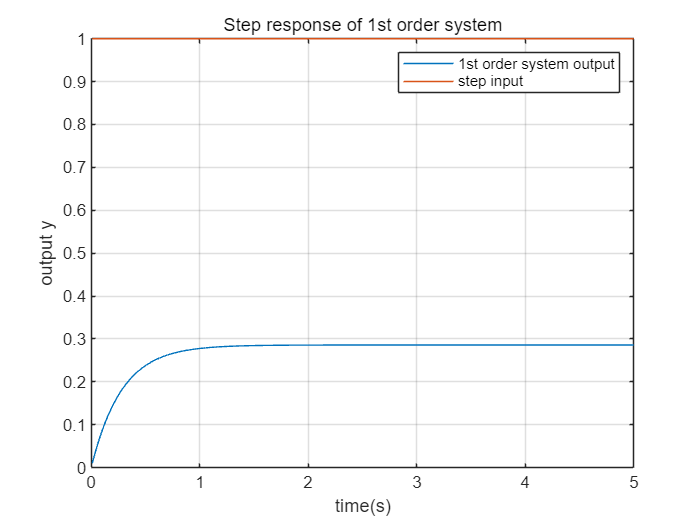

rng(0);
timestep = 0.01;
Time = 5;
time = linspace(0, Time, Time/timestep + 1);

real_theta = [-2, 1];

y = 0;                          % y(t)
prev_y = 0;                     % y(t-1)
r = 1;                          %%%% Unit step input %%%%
u = 0;                          % Initial input u
hat_theta = [1, 2];             % Initial model parameter
gain = [1, 3/2];                % Gain parameter
hat_theta_prev = hat_theta;     % Previous model parameter
dot_hat_theta = zeros([1, 2]);  % Update rule
hat_theta_data = [];            % Empty array for collecting data
varphi = zeros([1, 2]);         % varphi function
error = 0;                      % Initializing error
output_data = [];

gamma_model = 10;                     % Update parameter

for k = 1 : length(time)
    if (k + 1 > length(time))
        break;
    end
    u = gain(1)*r - gain(2)*y;
    varphi = [y, u];                    
    model_dot_y = varphi*hat_theta';    % dot_output from reference model
    real_dot_y = varphi*real_theta';    % Assumption : we can get dot y data
    y = prev_y + real_dot_y*timestep;   % Plant model output update
    
    %%% update parameter based on MIT rule %%%
    error = real_dot_y - model_dot_y;
    dot_hat_theta = gamma_model*error*varphi;
    hat_theta = hat_theta + dot_hat_theta*timestep;
    output_data = [output_data, y];
    hat_theta_data = [hat_theta_data, hat_theta'];
    prev_y = y;
end

outputy = plot(time(2:end), output_data);
hold on; grid on;
stepinput = plot(time(2:end), ones([length(time(2:end)), 1]));
xlabel("time(s)"); ylabel("output y"); title("Step response of 1st order system");
legend([outputy, stepinput], {"1st order system output", "step input"});
hold off;

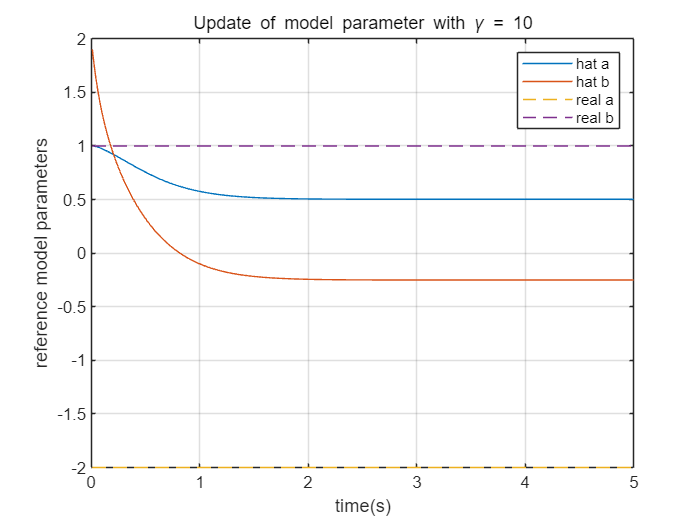

hata = plot(time(2:end), hat_theta_data(1, 1:end));
hold on; grid on;
hatb = plot(time(2:end), hat_theta_data(2, 1:end));
reala = plot(time(2:end), -2*ones([length(time(2:end)), 1]), '--');
realb = plot(time(2:end), 1*ones([length(time(2:end)), 1]), '--');
legend([hata, hatb, reala, realb], {"hat a", "hat b", "real a", "real b"});
xlabel("time(s)"); ylabel("reference model parameters"); title("Update of model parameter with \gamma = 10");
hold off;

MIT rule을 사용하여 reference model을 갱신해 1차 시스템의 파라미터들이 약 $\hat{a}\simeq0.5$, $\hat{b}\simeq-0.25$에 수렴한 것을 확인했다. 이는 error를 이용한 update rule로 인해서 발생한 문제라고 추측하고 있다. $J$는 $\dot{y}$의 오차에 대한 cost function이기 때문에 reference model의 $\dot{y}$와 실제 1차 시스템의 $\dot{y}$를 최소화하는 방향으로 $\hat{\theta}$가 갱신된다. 따라서 step input을 output $y$가 잘 추종하기 위해선 시스템에 먼저 input을 인가해 output data를 도출한 후 유사한 파라미터를 획득해 시스템 파라미터를 갱신하는 방식으로 접근하는 것이 옳다고 생각한다.

## c)

초기 값 $(\hat{a}_0 = 0, \hat{b}_0 = 4)$일 때 a)에서 설정한 제어이득 $(k_1, k_2)$을 적용한 제어기와 적용 규칙을 적용한 적응제어기를 각각 설계하고 0초∼5초 구간동안 계단 입력 $r(t) = 1$에 대한 출력 $y, u, (\hat{a}, \hat{b})$의 시간반응을 그래프로 나타내고, 결과를 비교하여라.

***sol)***

timestep = 0.01;
Time = 5;
time = linspace(0, Time, Time/timestep + 1);

real_theta = [-2, 1];
real_dot_y = 0;

y = 0;                          % y(t)
prev_y = 0;                     % y(t-1)
model_dot_y = 0;                % \dot{y}
r = 1;                          %%%% Unit step input %%%%
u = 0;                          % Initial input u
hat_theta = [0, 4];             % Initial model parameter
gain = [1, 3/2];                % Gain parameter
hat_theta_prev = hat_theta;     % Previous model parameter
dot_hat_theta = zeros([1, 2]);  % Update rule
hat_theta_data = [];            % Empty array for collecting data
varphi = zeros([1, 2]);         % varphi function
error = 0;                      % Initializing error
output_data = [];

gamma_model = 10;                     % Update parameter

for k = 1 : length(time)
    if (k + 1 > length(time))
        break;
    end
    u = gain(1)*r - gain(2)*y;
    varphi = [y, u];                    
    model_dot_y = varphi*hat_theta';    % dot_output from reference model
    real_dot_y = varphi*real_theta';    % Assumption : we can get dot y data
    y = prev_y + real_dot_y*timestep;   % Plant model output update
    
    %%% update parameter based on MIT rule %%%
    error = real_dot_y - model_dot_y;
    dot_hat_theta = gamma_model*error*varphi;
    hat_theta = hat_theta + dot_hat_theta*timestep;
    output_data = [output_data, y];
    hat_theta_data = [hat_theta_data, hat_theta'];
    prev_y = y;
end

outputy = plot(time(2:end), output_data);
hold on; grid on;
stepinput = plot(time(2:end), ones([length(time(2:end)), 1]));
xlabel("time(s)"); ylabel("output y"); title("Step response of 1st order system");
legend([outputy, stepinput], {"1st order system output", "step input"});
hold off;

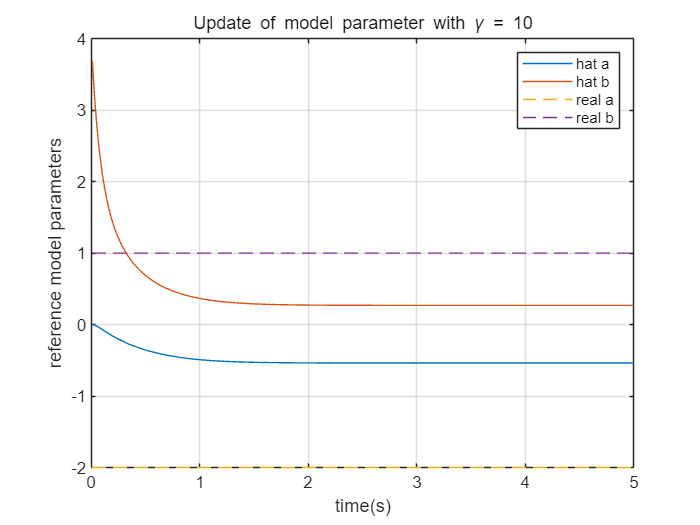

hata = plot(time(2:end), hat_theta_data(1, 1:end));
hold on; grid on;
hatb = plot(time(2:end), hat_theta_data(2, 1:end));
reala = plot(time(2:end), -2*ones([length(time(2:end)), 1]), '--');
realb = plot(time(2:end), 1*ones([length(time(2:end)), 1]), '--');
legend([hata, hatb, reala, realb], {"hat a", "hat b", "real a", "real b"});
xlabel("time(s)"); ylabel("reference model parameters"); title("Update of model parameter with \gamma = 10");
hold off;

위의 b) 문제에서 parameter estimation 그래프보다 실제 값에 유사하게 수렴하는 모습을 확인할 수 있다. 앞서 b)에서도 언급했듯 현재 $J$는 $\dot{y}$의 오차에 대한 cost function이기 때문에 위 모델은 reference model의 $\dot{y}$와 실제 1차 시스템의 $\dot{y}$를 최소화하는 방향으로 $\hat{\theta}$가 갱신된다. 또한 앞서 설계된 gain $(k_1, k_2)$는 $(\hat{a}_0, \hat{b}_0)$를 기준으로 설계됐기에 해당 설계 parameter를 실제 적용했을 때 step input response가 약 $0.258$에 가까워진 것을 바탕으로 실제 continuous transfer function의 steady state response가 $1/3.5$에 수렴하는 것과 유사함을 확인할 수 있다. 이는 갱신한 모델 파라미터가 직접적으로 1st order system에 영향을 주지 않고, gain $(k_1, k_2)$가 초기 잘못된 추정으로 설정됐기 때문임을 알 수 있다. 